# Lab 3 Challenges

## Challenge 1

Improve the contrast of a lake and tree image store in file *lake&tree.png* use any technique you have learned in this lab. Compare your results with others in the class.

#### Image Analysis

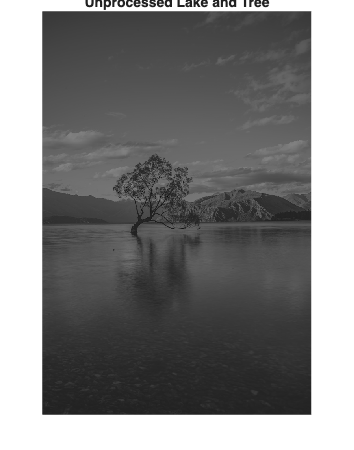

f = imread('inputs/lake&tree.png');

figure;
imshow(f);
title('Unprocessed Lake and Tree');

The image appears somewhat flat, with values concentrated towards a midtone grey.

First we could have a look at the histogram:

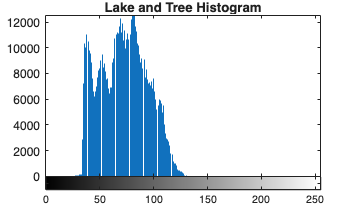

figure;
imhist(f); 
title('Lake and Tree Histogram');


disp('----------------------------------------');

----------------------------------------


#### Contrast Enhancement

We can see most of the values are distributed between around X=34 and X=130.

We can try contrast enhancement with `imadjust`:

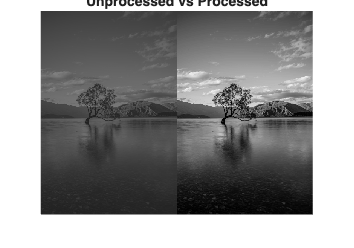

f = imread('inputs/lake&tree.png');
g = imadjust(f, [34/255 135/255], [0 1]);

% this enables you to spread out the histogram values

figure;
montage({f, g});
title('Unprocessed vs Processed');

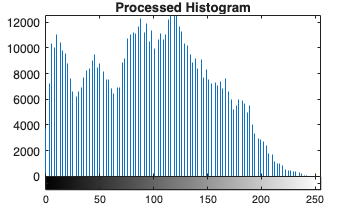

imwrite(g, 'challenge-1-outputs/contrast-enhancement.png');
figure;
imhist(g); 
title('Processed Histogram');


disp('----------------------------------------');

----------------------------------------


We can see this is quite successful

#### Gamma Correction

We can also try gamma correction:

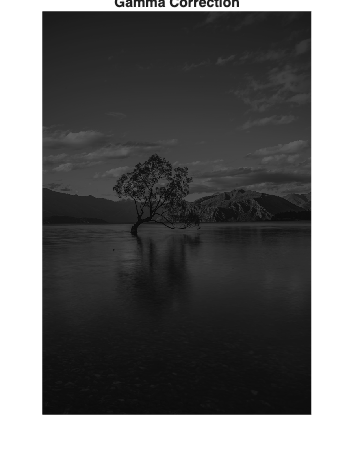

f = imread('inputs/lake&tree.png');

g2 = imadjust(f, [ ], [ ], 1.5);
figure;
imshow(g2); 
title('Gamma Correction');

imwrite(g2, 'challenge-1-outputs/gamma-correction.png');

disp('----------------------------------------');

----------------------------------------


This is not very successful at all - even when adjusting the gamma value. The image is not too bright or too dark - it's just in the middle so this technique doesn't help so much. 

#### Contrast-Stretching

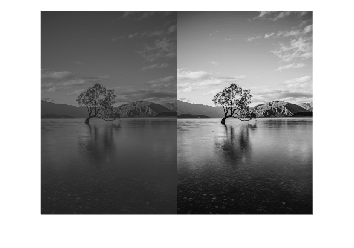

f = imread('inputs/lake&tree.png');
r = double(f);  % uint8 to double conversion
k = mean2(r);   % find mean intensity of image
E = 4;
s = 1 ./ (1.0 + (k ./ (r + eps)) .^ E);
g3 = uint8(255*s);
montage({f, g3});

imwrite(g3, 'challenge-1-outputs/contrast-stretching-e4.png');

Contrast stretching with a low E value does not work very well, but a higher E value improves the image quality. E controls the steepness - a larger E makes the technique very similar to thresholding. 

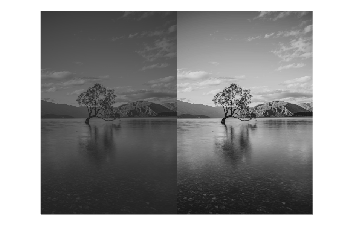

f = imread('inputs/lake&tree.png');
r = double(f);  % uint8 to double conversion
k = mean2(r);   % find mean intensity of image
E = 3;
s = 1 ./ (1.0 + (k ./ (r + eps)) .^ E);
g4 = uint8(255*s);
montage({f, g4});

imwrite(g4, 'challenge-1-outputs/contrast-stretching-e3.png');

disp('----------------------------------------');

----------------------------------------


Reducing the value of E enables a subtler output. This approach is a bit more flexible compared to basic contrast enhancement.

#### Histogram Equalisation

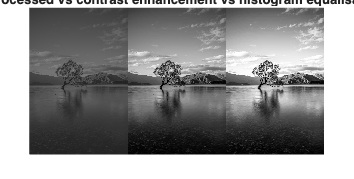

f = imread('inputs/lake&tree.png');
g = imadjust(f, [34/255 135/255], [0 1]);

h = histeq(g,256);
imwrite(h, 'challenge-1-outputs/histogram-equalisation.png');

figure;
montage({f, g, h})
title('Unprocessed vs contrast enhancement vs histogram equalisation');

This makes the image even more dramatic.

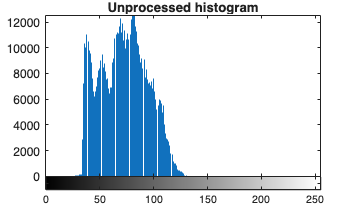

figure;
imhist(f); 
title('Unprocessed histogram');

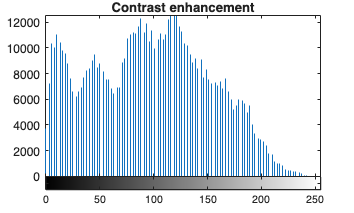

imhist(g);
title('Contrast enhancement');

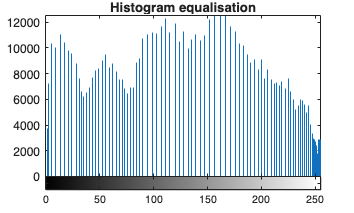

imhist(h); 
title('Histogram equalisation');


disp('----------------------------------------');

----------------------------------------


## Challenge 2

#### Image Analysis

Use the Sobel filter in combination with any other techniques, find the edge of the circles in the image file *circles.tif*. You are encouraged to discuss and work with your classmates and compare results.

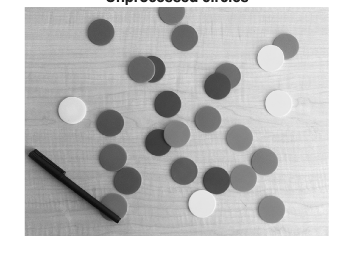

circles = imread('inputs/circles.tif');
figure;
montage({circles});
title('Unprocessed circles');

From the image there are circles with a variety of colours - which could potentially cause issues for processing.

Trying an initial sobel filter:

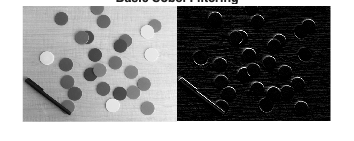

sobel = fspecial('sobel');
s = imfilter(circles, sobel);

figure;
montage({circles, s});
title('Basic Sobel Filtering');


imwrite(s, 'challenge-2-outputs/basic-sobel.png');

disp('----------------------------------------');

----------------------------------------


#### Removing wood texture (Median Filtering)

We want to remove the wood grain texture "noise". Median filtering can be useful here as the wood texture is somewhat similar to the salt and pepper effect, it can help reduce blurring of the circle edges.

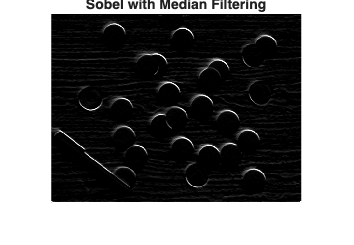

circles = imread('inputs/circles.tif');
% g_gamma = imadjust(circles, [ ], [ ], 0.5);

g_median = medfilt2(g_gamma, [5 5], 'zero');

sobel = fspecial('sobel');
s = imfilter(g_median, sobel);

figure;
imshow(s);
title('Sobel with Median Filtering');


imwrite(s, 'challenge-2-outputs/median-filtering-sobel.png');

 We can validate this by comparing to other filtering techniques:

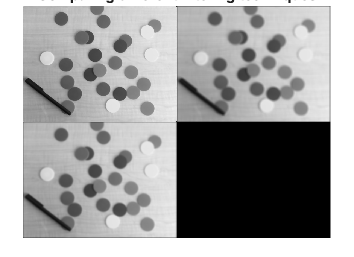

w_box = fspecial('average', [9 9]);
w_gauss = fspecial('Gaussian', [13 13], 2); 

g_box = imfilter(circles, w_box, 0);
g_gauss = imfilter(circles, w_gauss, 0);
g_median = medfilt2(circles, [5 5], 'zero');

figure;
montage({g_median, g_box, g_gauss});
title('Comparing different filtering techniques');

disp('----------------------------------------');

----------------------------------------


The boundaries of the circles become much to blurred when using a box filter or gaussian filter - median filtering is best here for preserving detail - however it does cause the differentiation between the white circles and the wood background to become quite bad - we can try to fix this by using gamma correction:

#### Using gamma correction to rebalance after median filtering

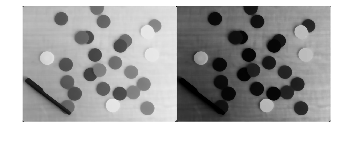

circles = imread('inputs/circles.tif');

g_median = medfilt2(circles, [9 9], 'zero');
g_gamma = imadjust(g_median, [ ], [ ], 3);

s1 = imfilter(g_median, sobel);
s2 = imfilter(g_gamma, sobel);

figure;
montage({g_median, g_gamma});

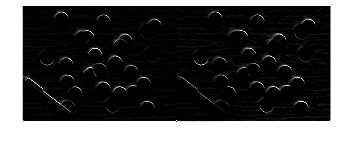

title('Applying gamma correction to median filtering');

montage({s1, s2});

----------------------------------------


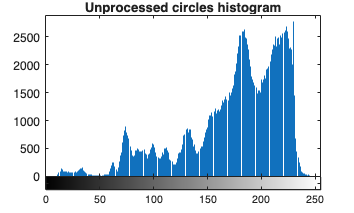

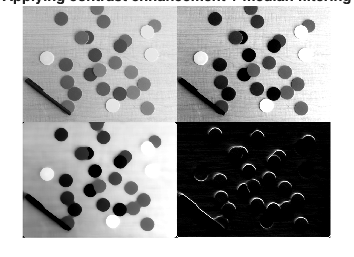

----------------------------------------


title('Comparing sobel with and without gamma correction');

disp('----------------------------------------');

#### Recapturing (lower) lost edges (by inverting the image)

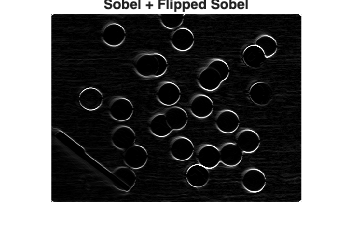

circles = imread('inputs/circles.tif');

g_median = medfilt2(circles, [9 9], 'zero');
g_gamma = imadjust(g_median, [ ], [ ], 3);

sobel = fspecial('sobel');
s = imfilter(g_gamma, sobel);

g_flipped = imadjust(g_gamma, [0 1], [1 0]); % flipping
s_flipped = imfilter(g_flipped, sobel);

s_combined = s + s_flipped;

figure;
imshow(s_combined);
title('Sobel + Flipped Sobel');


imwrite(s_combined, 'challenge-2-outputs/sobel-combination.png');

disp('----------------------------------------');

----------------------------------------


If you reverse the image you are able to extract the opposite edges that were missing from the other processing operation. 

We can add these two images together to get a nicer representation of the full circles. However some of the circles are still lost - how can we recover them?

#### Recapturing lost edges (with a different sobel orientation)

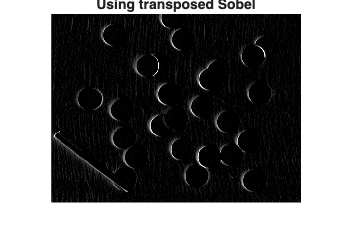

% after discussing with others one suggestion was to use a different orientation for sobel:
circles = imread('inputs/circles.tif');
h = fspecial('sobel');
h = h';   % transpose for vertical
s = imfilter(circles, h);
figure;
imshow(s);
title('Using transposed Sobel');


disp('----------------------------------------');

----------------------------------------


#### Putting everything together

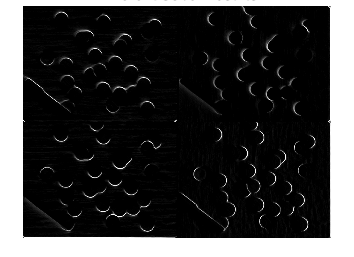

circles = imread('inputs/circles.tif');

g_gamma = imadjust(circles, [ ], [ ], 2);
g_invert = imadjust(g_gamma, [0 1], [1 0]);

h = fspecial('sobel');

g1 = medfilt2(g_gamma, [15 15], 'zero');
s1 = imfilter(g1, h);

g2 = medfilt2(g_gamma, [15 15], 'zero');
s2 = imfilter(g2, h');

g3 = medfilt2(g_invert, [12 12], 'zero');
s3 = imfilter(g3, h);

g4 = medfilt2(g_invert, [10 10], 'zero');
s4 = imfilter(g4, h');

figure;
montage({s1,s2,s3,s4})
title("Different Sobel Results")

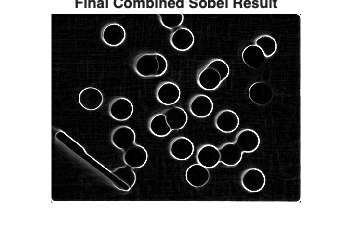


% sc = 0.5*s1 + 0.8*s2 + 1*s3 + 1*s4;
% sc = 1.2*s1 + 1*s2 + 2.5*s3 + 2.5*s4;

sf = s1 + s2 + s3 + s4;

figure;
imshow(sf)
title("Final Combined Sobel Result")


imwrite(sf, 'challenge-2-outputs/final-sobel.png');

disp('----------------------------------------');

----------------------------------------


## Challenge 3

*office.jpg* is a colour photograph taken of an office with bad exposure. Use whatever means at your disposal to improve the lighting and colour of this photo.

#### Image Analysis

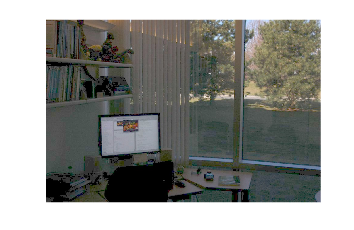

office = imread('inputs/office.jpg');
montage({office});

This is a colour image so slightly different techniques may need to be used. 

Can we try splitting and then recombining the image?

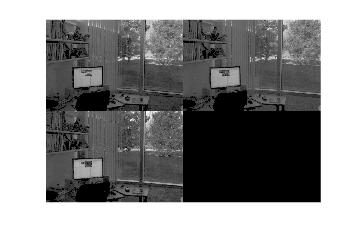

[R,G,B] = imsplit(office);
montage({R,G,B});

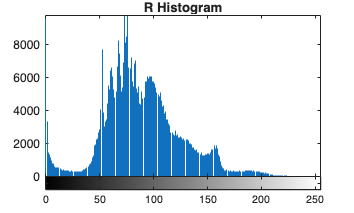


figure;
imhist(R);
title("R Histogram")

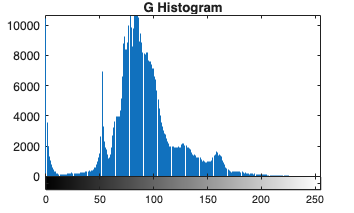


figure;
imhist(G);
title("G Histogram")

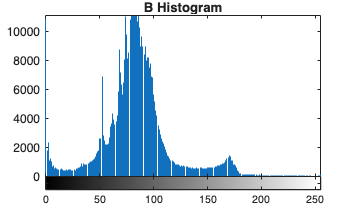


figure;
imhist(B);
title("B Histogram")


disp('----------------------------------------');

----------------------------------------


#### Boosting each split RGB channel

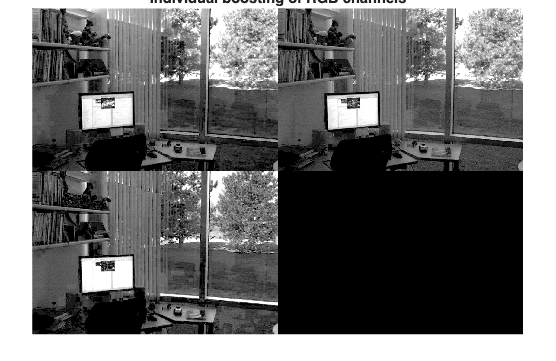

office = imread('inputs/office.jpg');
[R,G,B] = imsplit(office);

r = imadjust(R, [40/255 160/255], [0 1]);
g = imadjust(G, [40/255 160/255], [0 1]);
b = imadjust(B, [40/255 160/255], [0 1]);

figure;
montage({r, g, b})
title("Individual boosting of RGB channels")

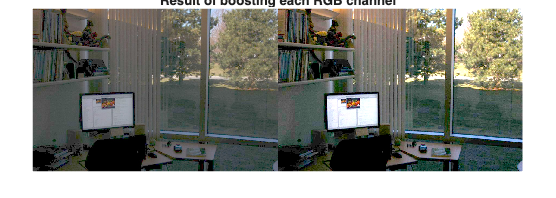


% recombining the channels:
I = cat(3, r, g, b);

figure;
montage({office, I});
title("Result of boosting each RGB channel")

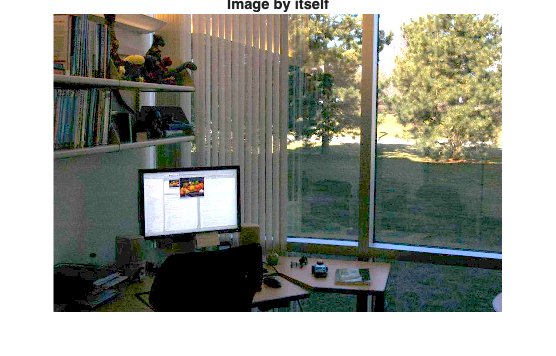


figure;
imshow(I)
title("Image by itself")

imwrite(I, 'challenge-3-outputs/rgb-boosted.png');
disp('----------------------------------------');

----------------------------------------


This improves the saturation and the contrast/exposure. 

#### Adjusting individual HSV channels

A better approach may be to increase the saturation and then improve the value individually.

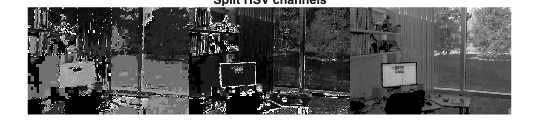

office = imread('inputs/office.jpg');
HSV = rgb2hsv(office);
[H,S,V] = imsplit(HSV);

figure;
montage({H,S,V}, 'Size', [1 3])
title("Split HSV channels")

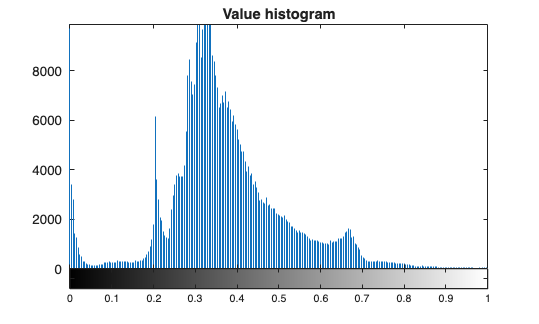


% we want to maintain hue, increase saturation and improve value - e.g.
% perform something similar to contrast stretching

% s = S+0.1; % adding saturation to every pixel
s = S*1.3; % scaling saturation

figure;
imhist(V);
title("Value histogram")

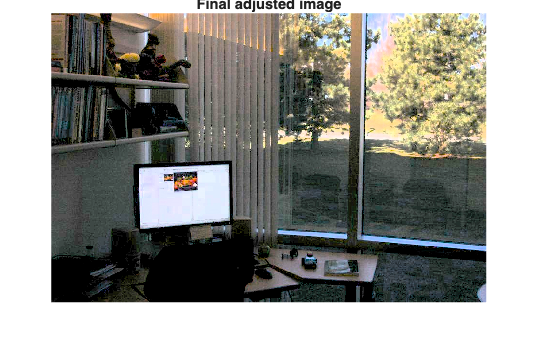


% adjusting V
v = imadjust(V, [0.22 0.58], [0 1]);


I = cat(3, H, s, v);
RGB = hsv2rgb(I);
figure;
imshow(RGB);
title("Final adjusted image")

imwrite(RGB, 'challenge-3-outputs/hsv-boosted.png');
disp('----------------------------------------');

----------------------------------------


The result is actually quite similar - saturation is just boosted more in the second technique and it is easier to adjust the saturation to the desired level.

# Lab 2 Challenges

## Challenge 1 (4/6 total challenges)

The grayscale image file *'assets/fillings.tif'* is a dental X-ray corrupted by noise. Find how many fills this patient has and their sizes in number of pixels.

#### Image Analysis

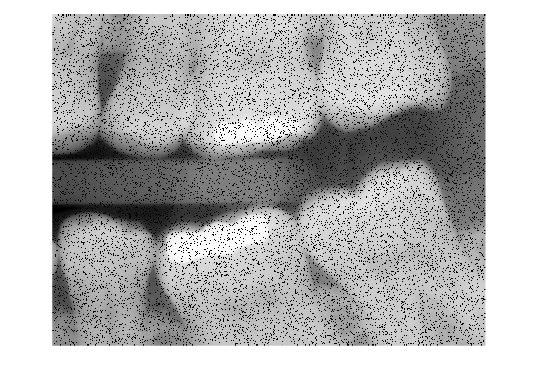

figure;
f = imread('inputs/fillings.tif');
title("Unprocessed")
imshow(f);

It would first make sense to try to remove the noise.

Compare which filtering technique best removes noise and maintains sharpness.

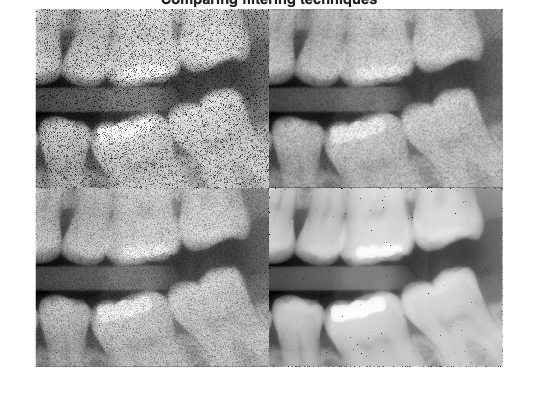

f = imread('inputs/fillings.tif');
w_box = fspecial('average', [6 6]);
w_gauss = fspecial('Gaussian', [6 6], 1.0);

g_box = imfilter(f, w_box, 0);
g_gauss = imfilter(f, w_gauss, 0);
g_median = medfilt2(f, [3 3], 'zero');

figure;
montage({f, g_box, g_gauss, g_median});
title("Comparing filtering techniques")

Median filtering best reveals fillings, but some detail is lost.

Try different median filtering approaches:

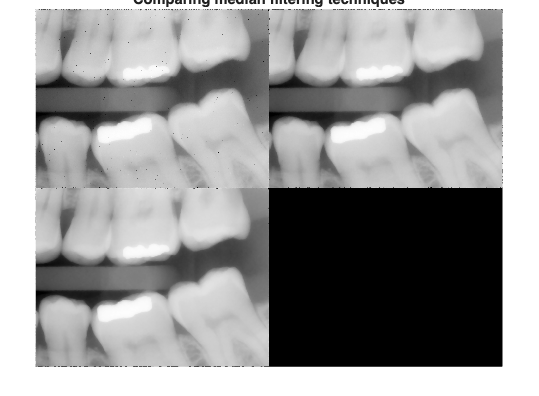

f = imread('inputs/fillings.tif');

g1 = medfilt2(f, [3 3], 'zero');
g2 = medfilt2(f, [5 5], 'zero');
g3 = medfilt2(f, [7 7], 'zero');

figure;
montage({g1, g2, g3});
title("Comparing median filtering techniques")

A size of [5,5] seems good

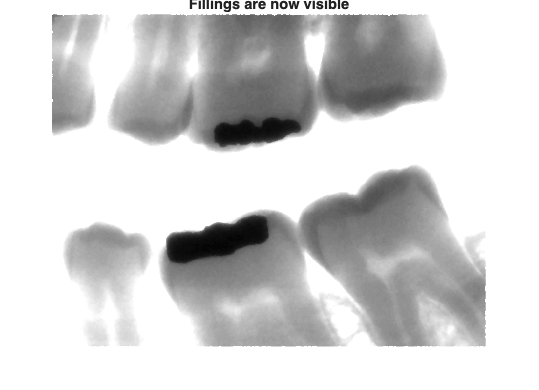

f = imread('inputs/fillings.tif');
g_median = medfilt2(f, [5 5], 'zero');
g1 = imadjust(g_median, [0 1], [1 0]);
g2 = imadjust(g1, [0.001 0.35], [0 1]);

figure;
imshow(g2);
title("Fillings are now visible");

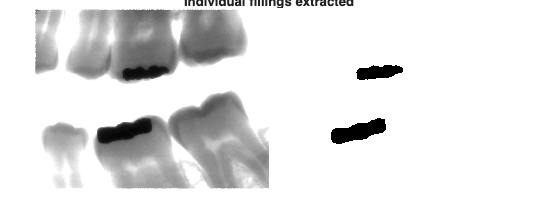


BW = imbinarize(g2, 0.3);

figure;
montage({g2, BW});
title("Individual fillings extracted");

Once we get to this point we might be able to binarize the image and work out something like the contours etc. so we can work out the size.

## Challenge 2

- The file *'assets/palm.tif'* is a palm print image in grayscale. Produce an output image that contains the main lines without all the underlining non-characteristic lines.

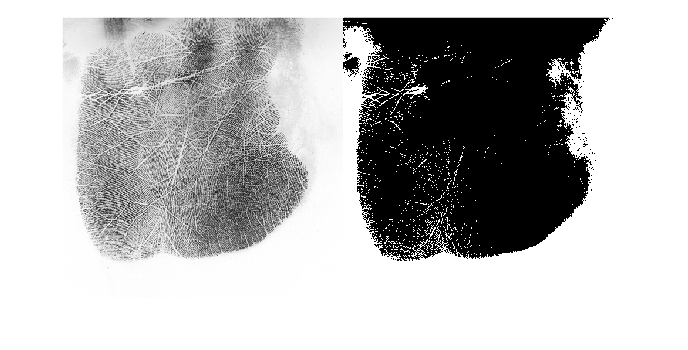

f = imread('assets/palm.tif');

I = imbinarize(f, 0.9);

SE = ones(1,1);

I = imdilate(I,SE);

I = imerode(I,SE);

% A1 = imdilate(BW, SE);
montage({f, I});

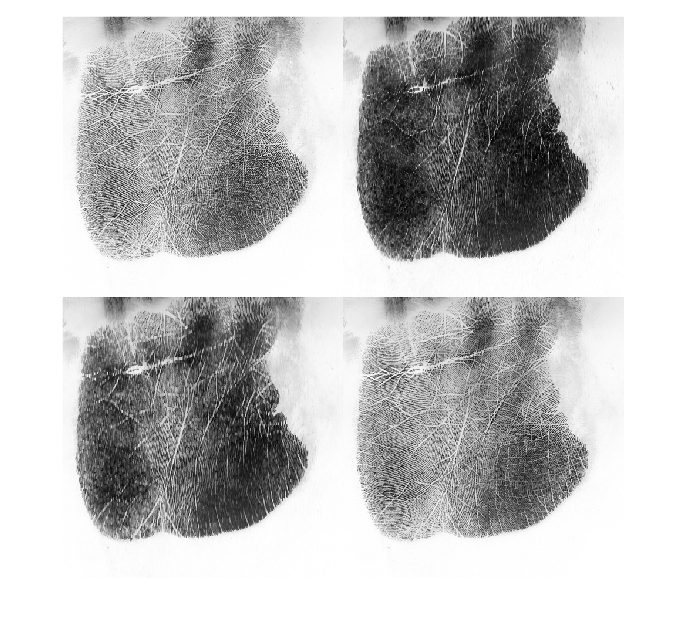

f = imread('assets/palm.tif');
se = ones(17,1);
g = imerode(f, se);
fo = imopen(f, se);     % perform open to compare
fr = imreconstruct(g, f);
bb = imbinarize(fr, 0.9);
montage({f, g, fo, fr, bb}, "size", [2 2])

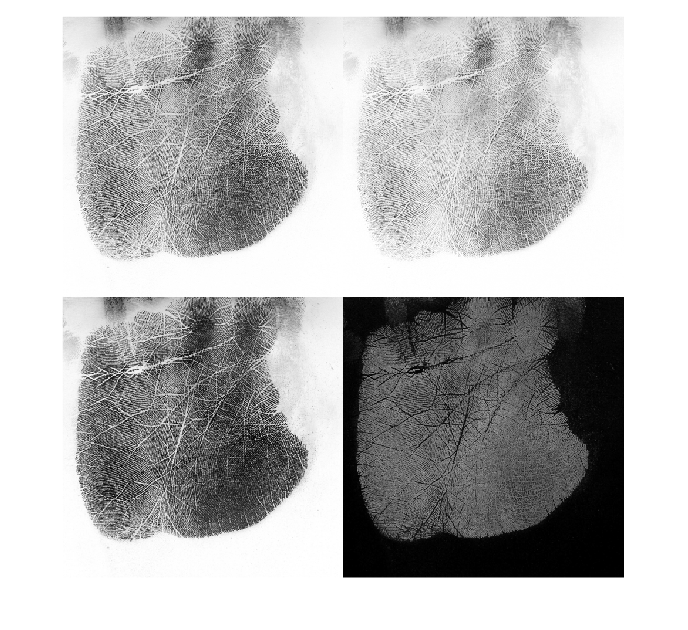

clear all; close all;
f = imread('assets/palm.tif');
se = strel('square',3);
gd = imdilate(f, se);
ge = imerode(f, se);
gg = gd - ge;
montage({f, gd, ge, gg}, 'size', [2 2])

## Challenge 3

The file *'assets/normal-blood.png'* is a microscope image of red blood cells. Using various techniques you have learned, write a Matlab.m script to count the number of red blood cells.

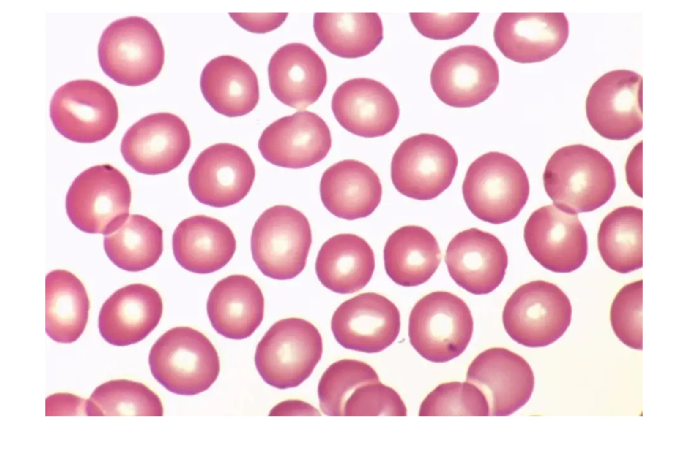

f = imread('assets/normal-blood.png');

montage({f});